# 対数損失と較正値

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear
clc
close all
rng(3); %ここのコメントを外すと書籍と同じグラフになります．

実際の勝率をp，予測勝率をwHatValとし，N試合の予測シミュレーションをおこなう．

N=100;plotData=[];
for p=0.1:0.1:0.9
    for wHatVal=0.5:0.1:0.9

実際の勝敗wは確率pと一様乱数でつくる(シミュレーションする)

        w=((rand(N,1))>=p)==0;
        wHat=ones(N,1)*wHatVal;
        logLoss=-mean(w.*log2(wHat) + (1-w).*log2(1-wHat));
        calibVal=sum(wHat)/sum(w);
        plotData=[plotData; ...
            logLoss calibVal p wHatVal];
    end
    plotData=[plotData;nan(1,4)];
end

plotData2=rmmissing(sortrows(plotData,4));

ind=1;
while true
    if ind+1<=size(plotData2,1) ...
            & plotData2(ind,4)~=plotData2(ind+1,4)
        plotData2=[plotData2(1:ind,:); nan(1,4); plotData2(ind+1:end,:)];
        ind=ind+1;
    end
    ind=ind+1;
    if ind>size(plotData2,1)
        break;
    end
end

それぞれの対数損失と較正値を図示する．

figure;
plot(plotData(:,1),plotData(:,2),'o:');
set(gca,'fontname','メイリオ')
grid on;hold on;
plot(plotData2(:,1),plotData2(:,2),'--');

ind = plotData(:,4)==0.9 & plotData(:,3)<0.6;
tmpData=plotData(ind,:);
for n1=1:size(tmpData,1)
    text(tmpData(n1,1)+0.05,tmpData(n1,2),['$p_w=' num2str(tmpData(n1,3)) '$'], ...
        'interpreter','latex','HorizontalAlignment','left')
end

ind = plotData2(:,3)==0.1;
tmpData=plotData2(ind,:);
for n1=1:size(tmpData,1)
    text(tmpData(n1,1),tmpData(n1,2)-0.05,['$\hat{w}=' num2str(tmpData(n1,4)) '$'], ...
        'interpreter','latex','HorizontalAlignment','right',...
        'VerticalAlignment','bottom')
end
rectangle('Position', [0.32 0.5 1.2-0.32 1.2-0.5]);

xlabel('対数損失');ylabel('較正値');
exportgraphics(gcf,'fig_logloss_calib_example.pdf')
axis([0.32 1.2 0.5 1.2]);
ind = plotData(:,3)>=0.8;
tmpData=plotData(ind,:)

tmpData =     1.0000    0.6329    0.8000    0.5000
    0.8306    0.7143    0.8000    0.6000
    0.8324    0.9459    0.8000    0.7000
    0.7619    1.0256    0.8000    0.8000
    0.8494    1.1538    0.8000    0.9000
    1.0000    0.5618    0.9000    0.5000
    0.7721    0.6383    0.9000    0.6000
    0.6857    0.8140    0.9000    0.7000
    0.5219    0.8889    0.9000    0.8000
    0.5324    1.0227    0.9000    0.9000


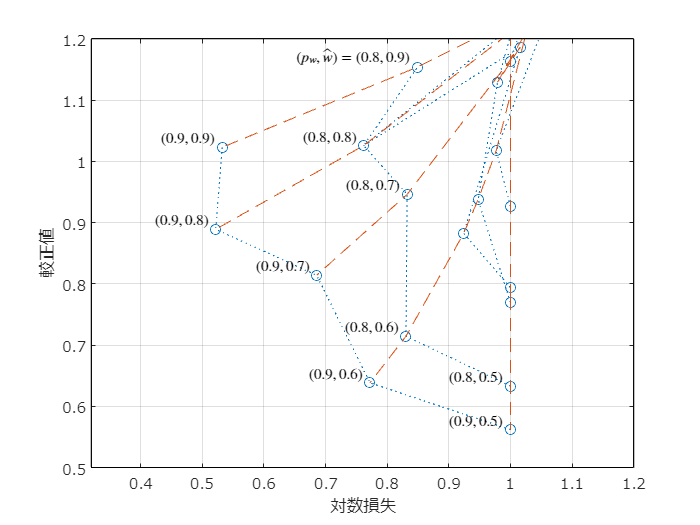

for n1=1:size(tmpData,1)
    if tmpData(n1,3)==0.8 & tmpData(n1,4)==0.9
    text(tmpData(n1,1)-0.01,tmpData(n1,2), ...
        ['$(p_w, \hat{w})=(' num2str(tmpData(n1,3)) ','  num2str(tmpData(n1,4)) ')$'], ...
        'interpreter','latex','HorizontalAlignment','right',...
        'VerticalAlignment','bottom')
    else

    text(tmpData(n1,1)-0.01,tmpData(n1,2),['$(' num2str(tmpData(n1,3)) ','  num2str(tmpData(n1,4)) ')$'], ...
        'interpreter','latex','HorizontalAlignment','right',...
        'VerticalAlignment','bottom')
    end
end
exportgraphics(gcf,'fig_logloss_calib_example_enlarged.pdf')

図の説明：

- カッコ内の数値は$(p_w, \hat{w})$ (実際の勝率と予測勝率)．

- 青点線は実際の勝率が同じ条件を結んだもの．

- 赤破線は予測勝率が同じ条件を結んだもの．